 tobs = load('myd.txt')

tobs = 	1.0e+-4 *

    0.0600   -0.1700    0.0400   -0.0400         0    0.1900   -0.0500    0.0500


% Construct system matrix for the ray path models
s2=sqrt(2);
G = [1,0,0,1,0,0,1,0,0;
     0,1,0,0,1,0,0,1,0;
     0,0,1,0,0,1,0,0,1;
     1,1,1,0,0,0,0,0,0;
     0,0,0,1,1,1,0,0,0;
     0,0,0,0,0,0,1,1,1;
     s2,0,0,0,s2,0,0,0,s2;
     0,0,0,0,0,0,0,0,s2];
 
% Get the singular values for the system matrix
[U,S,V] = svd(G);


% Find dimensions of G
[m,n] = size(G);

% Find system rank
p = rank(G);


Question 3

(a) Estimate model parameters given travel time observation

i. Use the generalized inverse of G, with the compact SVD decomposition.

% Let us compute the psuedoinverse using the compact SVD decomposition
Vp = V(:,1:p);

Up = U(:,1:p);

Sp = S(1:p,1:p);

Gt = Vp*inv(Sp)*Up';

m_dagger = Gt*tobs'

m_dagger = 	1.0e+-5 *

   -0.0369
   -0.8697
    0.1399
    0.0303
   -0.6702
    0.2732
    0.9732
    0.2066
    0.3536


ii. Use available software, e.g. the backslash operator in MATLAB.

m_bs = G\tobs'

m_bs = 	1.0e+-4 *

   -0.0070
   -0.0696
         0
   -0.0143
   -0.0637
    0.0413
    0.1180
         0
    0.0354


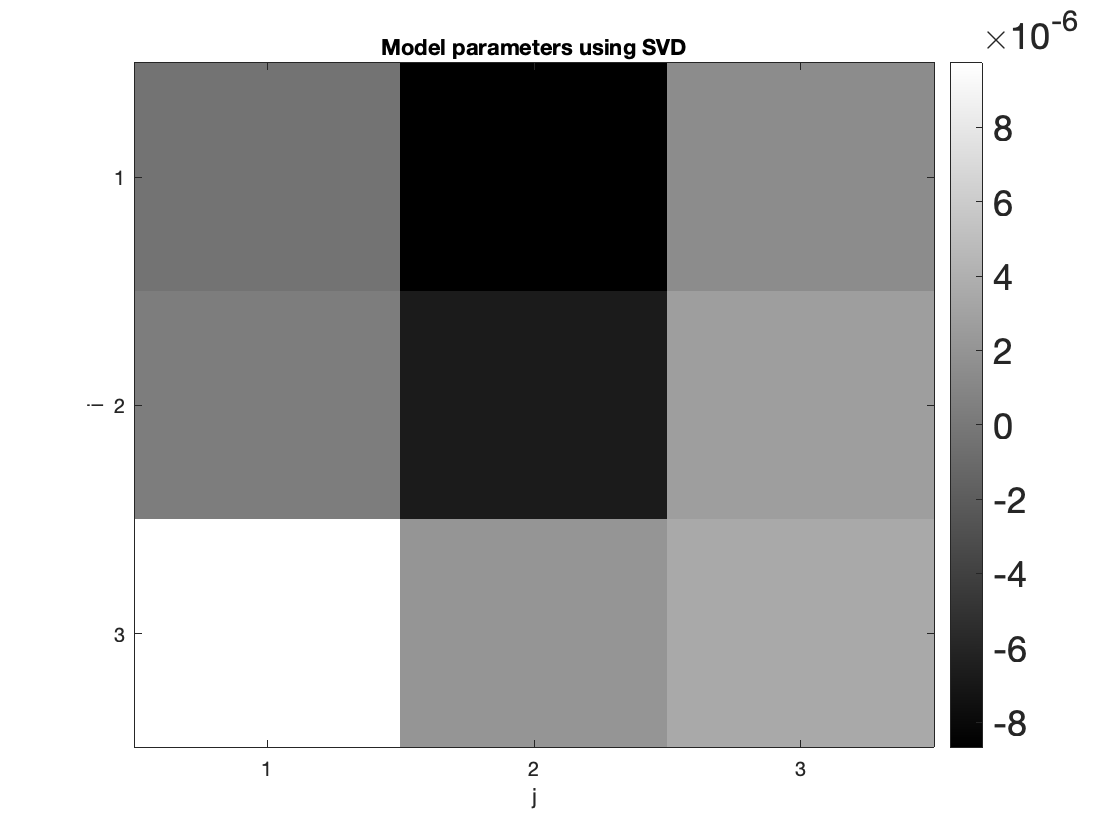

figure(1)
clf
colormap('gray')
imagesc(reshape(m_dagger,3,3)');
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Model parameters using SVD')

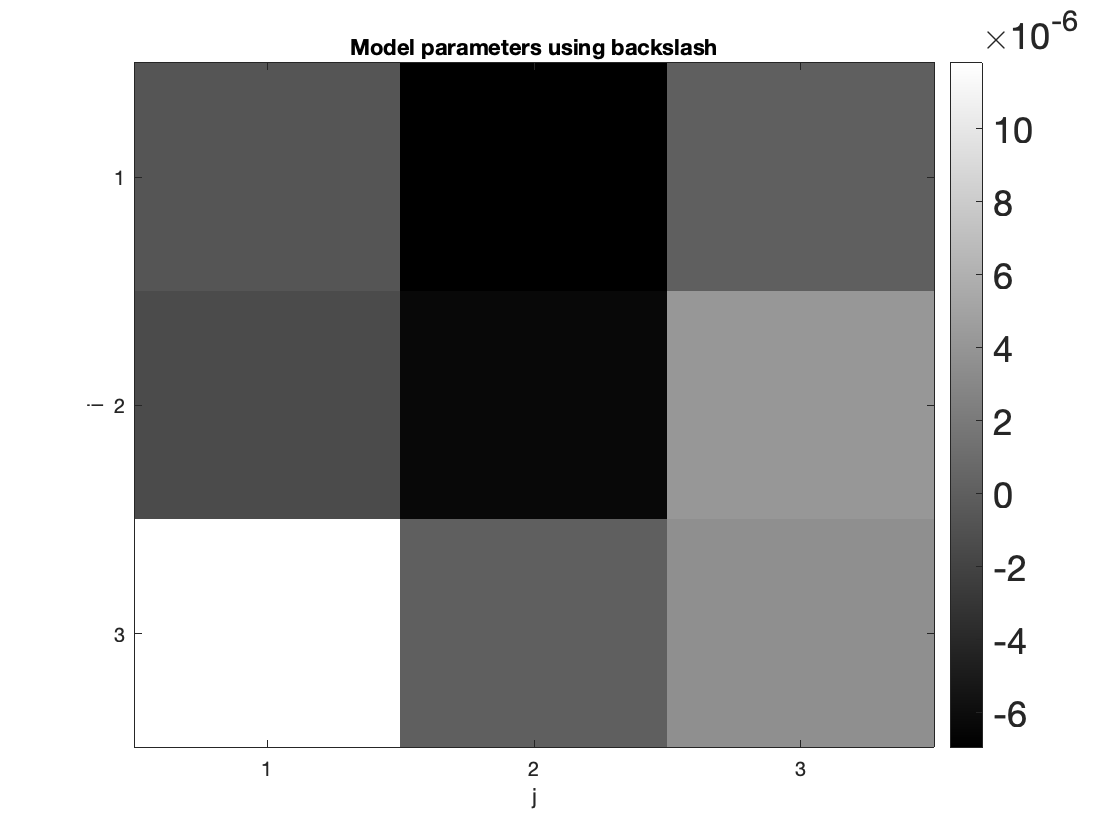

figure(2)
clf
colormap('gray')
imagesc(reshape(m_bs,3,3)');
%caxis([-0.1 1.0])
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Model parameters using backslash')

% Predict data using SVD parameter estimated model

t_dagger = G*m_dagger

t_dagger = 	1.0e+-4 *

    0.0967
   -0.1333
    0.0767
   -0.0767
   -0.0367
    0.1533
   -0.0500
    0.0500



% Predict data using backslash parameter estimated model

t_bs = G*m_bs

t_bs = 	1.0e+-4 *

    0.0967
   -0.1333
    0.0767
   -0.0767
   -0.0367
    0.1533
   -0.0500
    0.0500


norm_m = t_dagger - t_bs

norm_m = 	1.0e+-19 *

    0.0339
   -0.0169
   -0.0678
   -0.1016
   -0.0932
    0.1355
   -0.0847
    0.0508


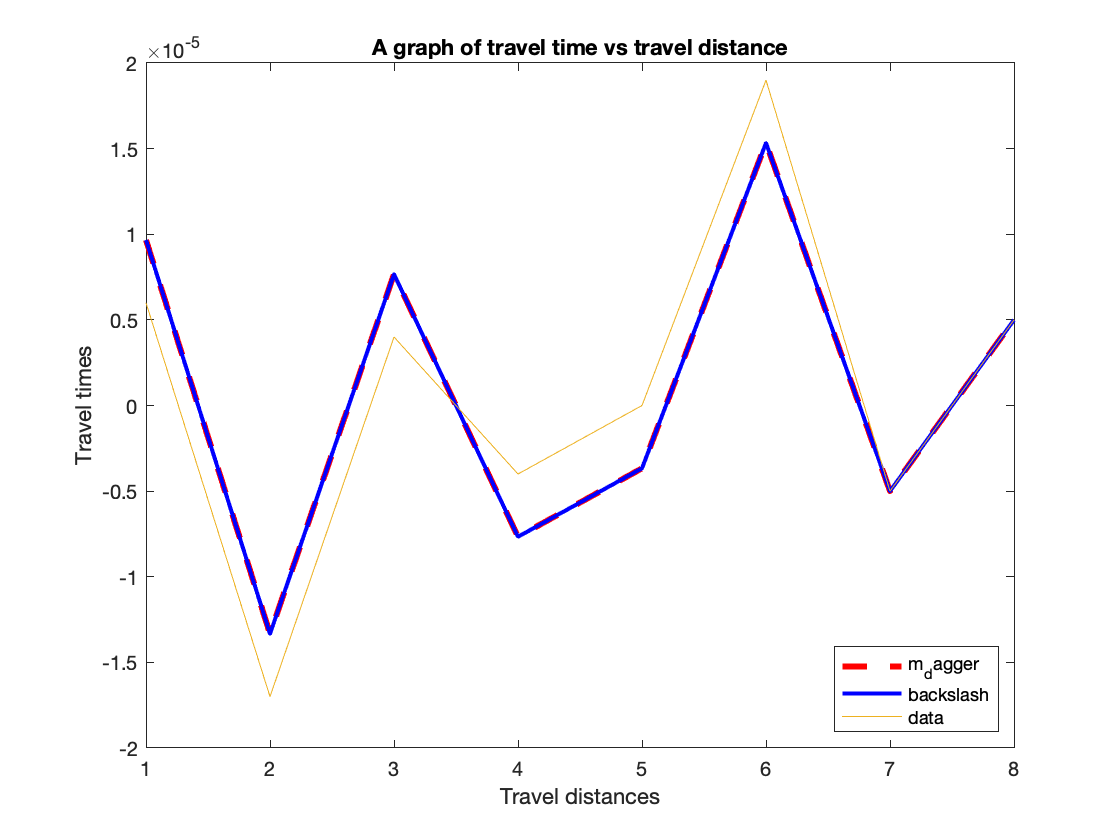

figure(3)
plot(t_dagger,'r--','LineWidth', 3)
hold on
plot(t_bs, 'b-', 'LineWidth',2)
hold on
plot(tobs, 'LineStyle',"-")
legend('m_dagger', 'backslash','data','Location','southeast')
title('A graph of travel time vs travel distance')
xlabel('Travel distances'); 
ylabel('Travel times')

**(b) Determine the dimension of the data null space. Plot the vectors in the data null space.**

% dimension of data null space

dim_dataNullSpace = m - p

dim_dataNullSpace = 1

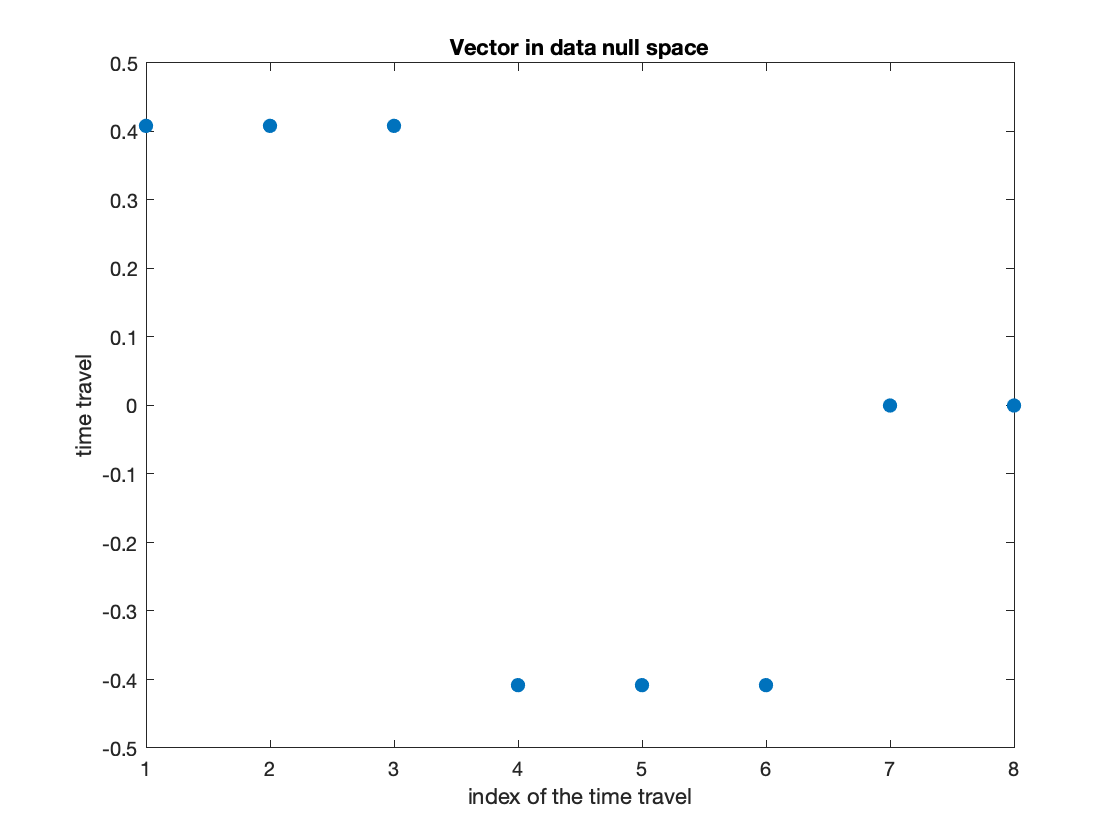

figure(3)
clf
plot(U(:,p+1),'.', 'MarkerSize', 20)
xlabel('index of the time travel')
ylabel('time travel')
title('Vector in data null space')

**c) Determine the dimension of the model null space. Plot the vectors in the model null space on 3 ×3 grids**

% Dimension of model null space

dim_modelNullSpace = n - p

dim_modelNullSpace = 2

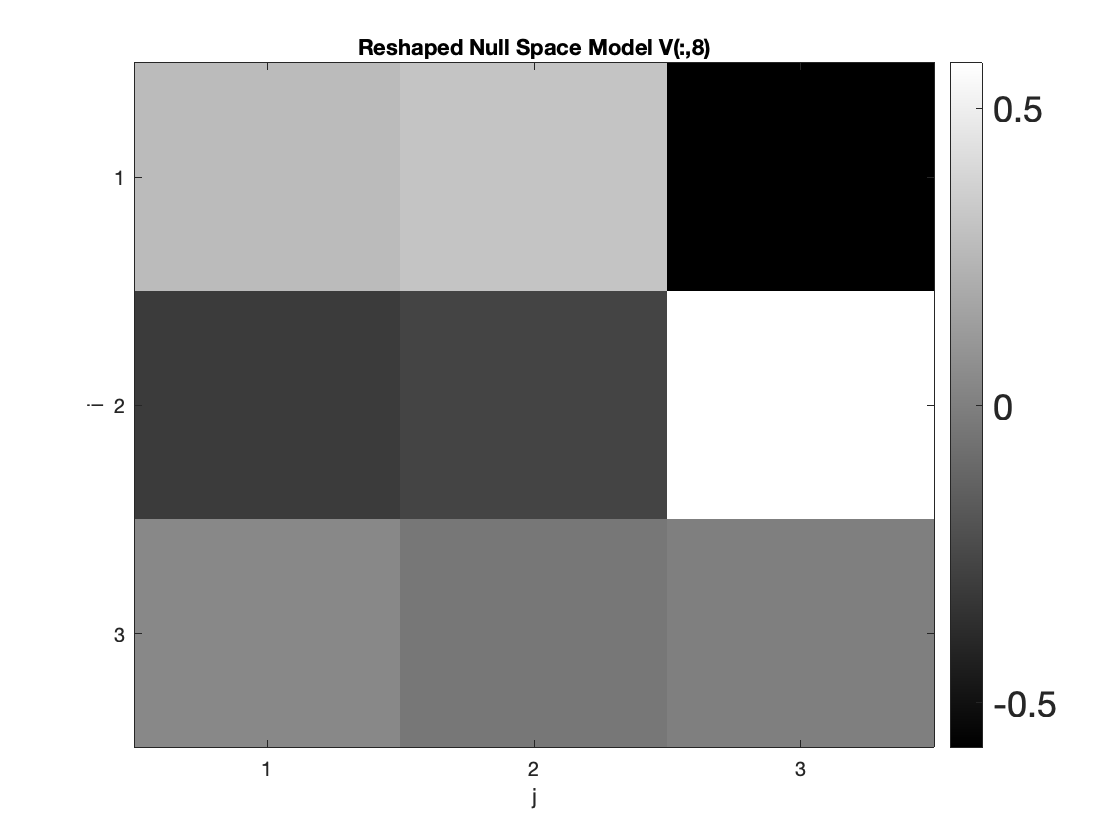


% Model null space vectors reshaped into matrices

m01 = reshape(V(:,p+1),3,3)';
m02 = reshape(V(:,p+2),3,3)';


% Display image of null space model V.,8
figure(4)
clf
colormap('gray')
imagesc(m01)
%caxis([-0.5 0.5]);
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Reshaped Null Space Model V(:,8)');

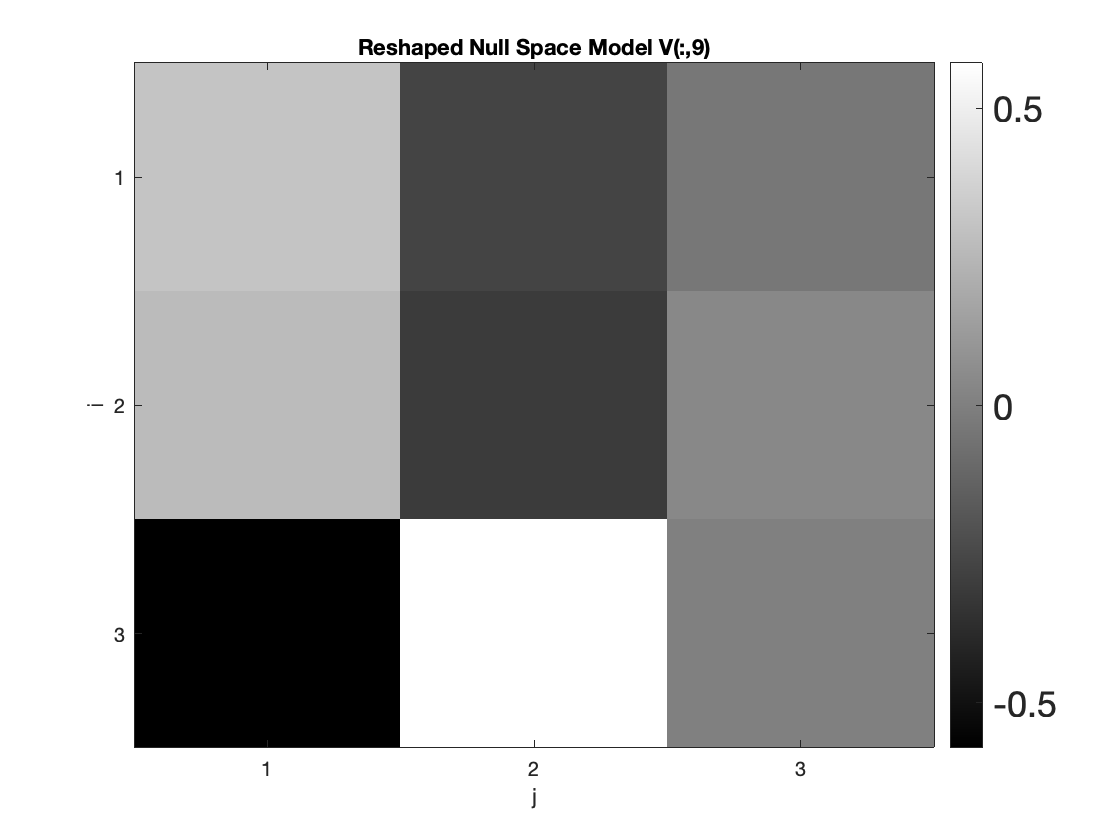


% Display image of null space model V.,9
figure(5)
clf
colormap('gray')
imagesc(m02)
%caxis([-0.5 0.5]);
set(colorbar,'Fontsize',18);
set(gca,'xtick',[1,2,3]);
set(gca,'ytick',[1,2,3]);
xlabel('j')
ylabel('i')
title('Reshaped Null Space Model V(:,9)');

**(d) Is it possible to have two sets of parameters that produce the same data? Explain why or why not, and give an example if possible.**

Yes, it possible to have two sets of parameters that produce the same data. In 3a) we obtained two different model parameters in (i) and (ii) that give us we the same predicted data. This is because the model parameter lie in the model null space, then any linear combination of these null space models that lie in the null space can be added to a particular model to obtain the same fitted data.

Example:

% Get a new parameter model by adding a linear combination of the null
% space vector to m_dagger

m_new = m_dagger + 2*V(:,8) + 3*V(:,9);
% Compute a new predicted data
t_new = G*m_new;
% Compare the new predicted data to the m_dagger predicted data
error = t_new-t_dagger

error = 	1.0e+-14 *

    0.0019
   -0.1420
   -0.0049
    0.2037
   -0.2289
   -0.1198
    0.0395
   -0.0428


**(e) Is it possible to have two sets of data that produce the same model parameters? Explain why or why not, and give an example if possible.**

Yes, it possible to have two sets of data that produce the same model paramters. Because the data lie in the data null space, then any linear combination of vectors in these data null space can be added to a data to obtain the same model parameters.

Example:

% Get a new parameter model by adding a linear combination of the null
% space vector to m_dagger

t_new = t_dagger + 2*U(:,8);
% Compute a new predicted data
m_new = Gt*t_new;
% Compare the new model parameter to the m_dagger
error = m_new-m_dagger

error = 	1.0e+-15 *

   -0.1536
    0.1886
    0.0594
    0.1976
    0.0006
    0.1347
   -0.0804
    0.0693
    0.1834
